### Importing data

%ncfile = NetCDFFile('run10FinalLeticia.nc');
ncfile = NetCDFFile('run18_day3000.nc');


% initialize wvt from file
wvt = WVTransform.waveVortexTransformFromFile(ncfile.path, iTime=Inf);
t = ncfile.readVariables('t');

E_model= wvt.transformToRadialWavenumber( wvt.Apm_TE_factor .* (abs(wvt.Ap).^2 + abs(wvt.Am).^2) );
E_model=E_model./(wvt.kRadial(2)-wvt.kRadial(1));
j=wvt.j;
kRadial=wvt.kRadial;

figure
pcolor(kRadial,j,log10(E_model))
kIndices = kRadial<wvt.forcingWithName("adaptive damping").k_damp;
jIndices = j > 0 & j < wvt.forcingWithName("adaptive damping").j_damp;
Ejk = E_model(jIndices,kIndices);
j = j(jIndices);
k = kRadial(kIndices);
pcolor(k,j,log10(Ejk))

dk = (k(2)-k(1));
sum(Ejk(:))*dk

% Ekj = Ekj.';

# Parametrical fit

### Initialize the toolbox

%Stratification 1 - Exponential
% f0=2*7.2921e-5*sind(latitude);
latExp=33;
L_gm = 1300;
N0 = 3*2*pi/3600;
N2funcExp = @(z) N0*N0*exp(2*z/L_gm);
LzExp=4000;
tic
igw = InternalGravityWaveSpectrum(N2funcExp,LzExp,nModes=42,nK=86,latitude=latExp);
toc

omegaFunc= @(k,jInd) interp1(igw.KRadialLog, igw.omega(jInd,:), k);

for ij=1:length(j)
    for ik=1:length(k)
        omega(ij,ik)= omegaFunc(k(ik),j(ij));
    end
end

### Visualizing frequency

c=7*10^-6;
% M2 band: width = c
lowerBound = M2omega - c/2;
upperBound = M2omega + c/2;

% Create logical mask where omega is within the M2 frequency band
mask = (omega >= lowerBound) & (omega <= upperBound);

jpcolor(log(omega))
colorbar
title('\omega(k, j) with red dots where it lies within the M2 band');

% Overlay red dots where omega is inside the M2 band
hold on;
[row, col] = find(mask);
scatter(col, row, 30, 'r', 'filled');

### Aproximation by eye

params= [7,3,1.4,4,1,7*10^-6];
f = @(params) igw.mySpectrum(params,k, j,Ejk);


## Params Guess

paramsGuess=params_out;

min = [1,-3, 0.1, 1, 0.1, 10^-6];
max = [10,3,5,10, 100, 10^-5];
options = optimset('TolX', 1e-6, 'TolFun', 1e-6,'MaxFunEvals', 1e5, 'MaxIter', 1e4, 'Display', 'iter');  % ajuste os valores
tic
[params_out,fval] = fminsearchbnd(f,paramsGuess,min,max,options)

params_out =    10.0000   -0.5523    3.7243    1.0000   34.6120    0.0000


fval = 0.9983

toc

Elapsed time is 134.451625 seconds.



%model_GM = igw.gmSpectrum(j_star=params_out(1),slope_j=params_out(2),slope_k=params_out(3),A=params_out(4));
model_GM = igw.generalSpectrum(j_star=params_out(1),slope_j=params_out(2),slope_k=params_out(3),A=params_out(4));
model_M2 = igw.tidalSpectrum(A=params_out(5),c=params_out(6));
S = @(k,jInd) model_GM(k,jInd) + model_M2(k,jInd);

%%
sum(Ejk(:)*(k(2)-k(1)))

ans = 3.5204

energySpectrum_jk = zeros(length(j),length(k));
for indj = 1:length(j)
    for indk = 1:length(k)
        energySpectrum_jk(indj,indk) = S(k(indk)+(dk/1.9),j(indj));
    end
end
sum(energySpectrum_jk(:)*(k(2)-k(1)))

ans = 3.3719

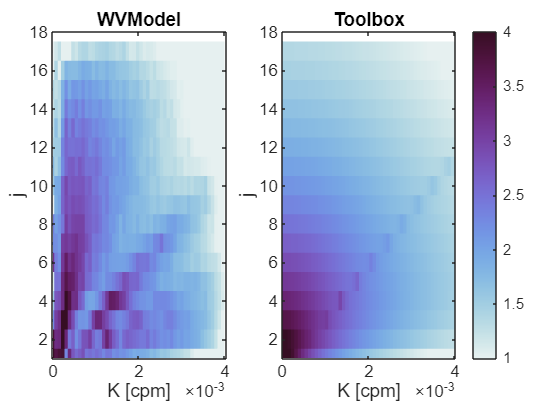

figure
tiledlayout(1,2, 'Padding', 'compact', 'TileSpacing', 'compact')

% Painel 1 - WVModel
nexttile
jpcolor(2*pi*k, j, log10(Ejk))
%colorbar
clim([1 4])
cmocean('dense')
title('WVModel')
xlabel('K [cpm]')
ylabel('j')

% Painel 2 - Toolbox
nexttile
jpcolor(2*pi*k, j, log10(energySpectrum_jk))
colorbar
clim([1 4])
cmocean('dense')
title('Toolbox')
xlabel('K [cpm]')
ylabel('j')

saveas(gcf, 'WVModel_vs_Toolbox_gm.png')  % saves as PNG


%exportgraphics(gcf, 'WVModel_vs_Toolbox_GM.pdf', 'ContentType', 'vector');

### What each param changes?

paramList = [
    3, 1.7, -0.9, 4, 7e-6, 120;   % (1,1)
    10, 1.7, -0.9, 4, 7e-6, 120;  % (1,2)
    15, 1.7, -0.9, 4, 7e-6, 120;  % (1,3)
    
    10, 1.0, -0.9, 4, 7e-6, 120;  % (2,1)
    10, 1.7, -0.9, 4, 7e-6, 120;  % (2,2)
    10, 4.0, -0.9, 4, 7e-6, 120;  % (2,3)
    
    10, 1.7, -0.5, 4, 7e-6, 120;  % (3,1)
    10, 1.7, -0.8, 4, 7e-6, 120;  % (3,2)
    10, 1.7, -2.0, 4, 7e-6, 120;  % (3,3)
    
    10, 1.7, -0.8, 1, 7e-6, 120;  % (4,1)
    10, 1.7, -0.8, 4, 7e-6, 120;  % (4,2)
    10, 1.7, -0.8, 8, 7e-6, 120;  % (4,3)
];

% Crie uma figura com subplots organizados
figure;
tiledlayout(4,3, 'Padding', 'compact', 'TileSpacing', 'compact');

% Nomes dos parâmetros, só para referência
paramNames = ["j^*", "slope_{kj}", "slope_j", "GM Amp", "c", "A"];

for idx = 1:size(paramList, 1)
    nexttile;
    
    params = paramList(idx,:);
    model = igw.gmSpectrumFunctionHandle(params);  % função geradora do modelo
    
    % Executa a função que plota o modelo
    objectiveFunction(igw, params, k, j, Ejk);
    
    % Determine qual parâmetro está variando nesta linha
    rowNum = ceil(idx / 3);
    colNum = mod(idx - 1, 3) + 1;
    
    % Pegue os 3 valores da linha correspondente
    startIdx = (rowNum - 1) * 3 + 1;
    lineParams = paramList(startIdx:startIdx+2, :);
    
    % Identifique qual coluna (parâmetro) está mudando
    varyingParamIdx = find(any(abs(diff(lineParams)) > 1e-8, 1));  % tolerância para float
    
    % Título simplificado com o valor da variável que muda
    title(sprintf('%s = %.3g', paramNames(varyingParamIdx), params(varyingParamIdx)));
end


## Params Guess

%j_star, slope_kj, slope_j, GMAmplitude, c, A
paramsGuess=[10, 1.7, -0.9, 4, 7e-6, 120];
fun= @(paramsGuess) igw.objectiveFunction(paramsGuess,k,j,Ejk);
tic
params_out = fminsearchbnd(fun,params,[1 0.1 -3 0.1 10^-7 0.1],[10 5 -0.1 10 10^-4 100])
toc



%%
sum(Ejk(:)*(k(2)-k(1)))
energySpectrum = igw.gmSpectrumFunctionHandle(params_out)
energySpectrum_jk = zeros(length(j),length(k));
for indj = 1:length(j)
    for indk = 1:length(k)
        energySpectrum_jk(indj,indk) = energySpectrum(k(indk)+(dk/1.9),j(indj));
    end
end
sum(energySpectrum_jk(:)*(k(2)-k(1)))


figure
tiledlayout(1,2)
nexttile
jpcolor(k,j,log10(Ejk))
nexttile
jpcolor(k,j,log10(energySpectrum_jk))

% FMatrix=wvt.FMatrix;
% GMatrix=wvt.GMatrix;

% UAm=wvt.UAm;
% UAp=wvt.UAp;
% [AmWavenumber,ApWavenumber] = wvt.transformToRadialWavenumber(UAm,UAp);
% 
% UA2= (AmWavenumber.*conj(AmWavenumber) + ApWavenumber.*conj(ApWavenumber));
% 
% Ekj = wvt.transformToRadialWavenumber( wvt.Apm_TE_factor .* (abs(wvt.Ap).^2 + abs(wvt.Am).^2) );

% u2 = zeros(14,44,22);
% 
% for jind = 1:wvt.Nj
%     F2this = FMatrix(jind,:).^2;
%     for Kind = 1:length(wvt.kRadial)
%         u2(jind,Kind,:)=UA2(jind,Kind)*F2this;
%     end
% end

% UAm=wvt.UAm;
% UAp=wvt.UAp;
% [AmWavenumber,ApWavenumber] = wvt.transformToRadialWavenumber(UAm,UAp);
% 
% UA2= (AmWavenumber.*conj(AmWavenumber) + ApWavenumber.*conj(ApWavenumber));

% u2 = zeros(14,44,22);
% 
% for jind = 1:wvt.Nj
%     F2this = FMatrix(jind,:).^2;
%     for Kind = 1:length(wvt.kRadial)
%         u2(jind,Kind,:)=UA2(jind,Kind)*F2this;
%     end
% end

% VAm=wvt.VAm;
% VAp=wvt.VAp;
% [AmWavenumber,ApWavenumber] = wvt.transformToRadialWavenumber(VAm,VAp);
% 
% VA2= (AmWavenumber.*conj(AmWavenumber) + ApWavenumber.*conj(ApWavenumber));

% v2 = zeros(14,44,22);
% 
% for jind = 1:wvt.Nj
%     F2this = FMatrix(jind,:).^2;
%     for Kind = 1:length(wvt.kRadial)
%         v2(jind,Kind,:)=VA2(jind,Kind)*F2this;
%     end
% end

% u2v2=u2+v2;
% uvVariance=squeeze(sum(sum(u2v2)));
% 
% %uvVarianceInterp=
% plot(flipup(uvVariance),wvt.z)

% u2=(wvt.u).^2;
% v2=(wvt.v).^2;
% 
% u2Mean=squeeze(mean(mean(u2,1),2));
% v2Mean=squeeze(mean(mean(v2,1),2));
% 
% HVVariance =u2Mean + v2Mean;

% plot(HVVariance,wvt.z);
% Ekj = wvt.transformToRadialWavenumber( wvt.Apm_TE_factor .* (abs(wvt.Ap).^2 + abs(wvt.Am).^2) );